# Analyze heat capacity from DR

This routine is intended at anaLzing Cp data acquired with our DR used in the Dynacool PPMS of the Lee lab

## To do: 

- Error bars:

-     For dT data, use standard deviation

-     For dCp values, add the SampHCErrmJmoleK field 

## Import data YTmVO4

Data = ImportCpDR('2018-07-31_TmVO4-LS5228-DR-HC180731.dat');
% Data0 = importCpSharedPPMS_('20180322_TmVO4-LS5228-MP3-Plt-HC1803_Cp.dat');
Data10 = ImportCpDR('DRHC_10YTmVO4-LS5251-DR-HC180511.dat');
Data15 = ImportCpDR('DRHC_15Y-TmVO4-LS5343-DR-HC180721.dat');
Data18 = ImportCpDR('2018-07-24_DR-HC_18Y-TmVO4-LS5348-DR-HC180724.dat');
Data20 = ImportCpDR('DRHC_20YTmVO4-LS5252-DR-HC180519.dat');
Data22 = ImportCpDR('2018-07-23_DR-HC_22Y-TmVO4-LS5344-DR-HC180723.dat');
Data24 = ImportCpDR('2018-07-25_DR-HC_24Y-TmVO4-LS5349-DR-HC180725.dat');
Data30 = ImportCpDR('DRHC_30YTmVO4-LS5335-DR-HC180526.dat');

## Concatenate them in a cell array

split = {Data; Data10; Data15; Data18; Data20; Data22; Data24; Data30};
L = length(split);

## Rename variables

isTableCol = @(t, thisCol) ismember(thisCol, t.Properties.VariableNames);
% function to test if a column exists in a table
for i=1:L% for doped samples measured in DR
    if isTableCol(split{i},'SampleTempKelvin')
        split{i}.Properties.VariableNames{'SampleTempKelvin'} = 'T';% rename the temperature column
    end
    if isTableCol(split{i},'FieldOersted')
        split{i}.Properties.VariableNames{'FieldOersted'} = 'H';% rename the magnetic field column
    end
    if isTableCol(split{i},'SampHCJK')% for samples measured in DR
        split{i}.Properties.VariableNames{'SampHCJK'} = 'Cp';% rename the heat capacity column
    elseif isTableCol(split{i},'SampHCmJmoleK')% for samples measured in shared PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    elseif isTableCol(split{i},'SampHCJmoleK')% for samples measured in Fisher He4 PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    end
end

## Remove NaN rows

for i=1:L
    split{i}(any(isnan(split{i}.T), 2), :) = [];% Remove rows where T is NaN
end

## Keep only data under zero magnetic field

for i=1:L%for all datasets
    split{i} = split{i}(round(split{i}.H,-1)==0,:);% keep only data at zero field
end
% split{L} = split{L}(round(split{L}.H,-1)==20000,:);% keep only data at 20000 Oe for the second TmAsO4 dataset

## Plot parameters for heat capacity

xlblTemp = 'Temperature (K)';
ylblCp = 'C_p (J\cdotmol^{-1}\cdotK^{-1})';
ttlCpY ='Heat capacity of Tm_{1-x}Y_xVO4';
ttlCpAs ='Heat capacity of TmAs_{1-x}V_xO4';

## Compute molar heat capacity

M = [283.87326% Molar mass of each sample, in g/mol
275.3902538
271.869006
269.4681552
266.3470492
266.2670208
264.6664536
258.6643266];
m = 1e-3*[0.38% mass in g of the sample on which each dataset was measured
0.13
0.24
0.045
0.25
0.59
0.76
0.14];
dpg = 1e-2*[0% Y content for each dataset
10.6
15.3%
18.1%
21.9%
22.0%
24.8%
31.5];
% split{1}.Cpmol = split{1}.Cp *1e-3;% molar heat capacity, in J/mol/K,
% starting from a heat capacity in mJ/mol/K as is measured in the shared PPMS
for i=1:L
    split{i}.Cpmol = split{i}.Cp *1e-6*M(i)/(m(i)*(1-dpg(i)));% molar heat capacity, in J/mol/K
    % starting from a heat capacity measured in microJoules per Kelvin, as is measured in the DR
    % Cpmol is calculated per mole of Tm3+ ions, hence the (1-dpg) factor in the denominator
end

## Plot the dataset for YTmVO4

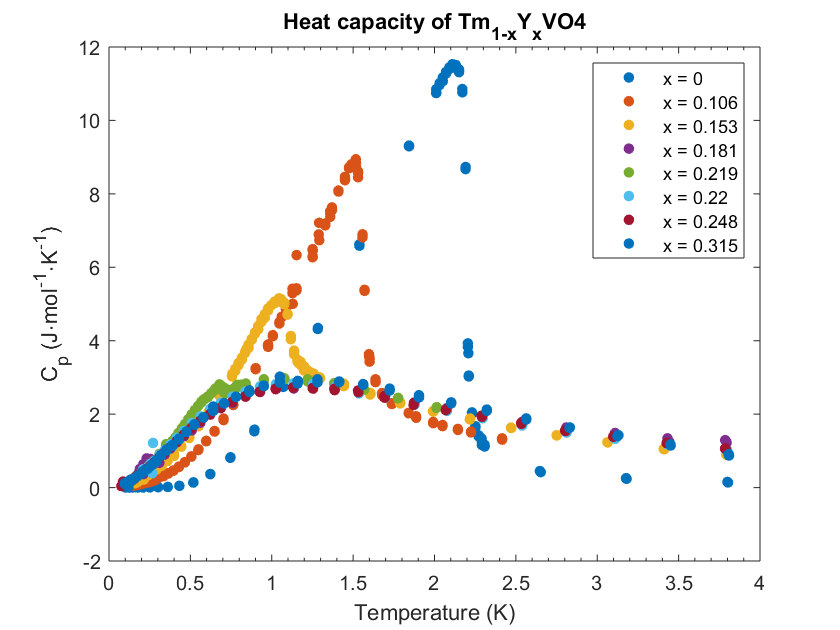

plotCpDoping(split,dpg,1,L,ttlCpY)

# Average data

## Sort each dataset by increasing value of temperature

for i=1:L
    srtd{i} = sortrows(split{i},{'T'});
%     [split{i}.T,wo] = sort(split{i}.T);
%     split{i}.Cp = split{i}.Cp(wo);
end
srtd = srtd';

## Test the temperature scattering between data points supposedL taken at the "same" temperature

4mK is the empirical maximal dispersion of data points taken consecutiveL at a given temperature. In order to check this, one can run the following code on the temperature variable T:

nrep = 3;% number of repetitions of the measurement at each temperature
% We want to compute the temperature separation between two data points
% that are NOT repetitions of the same measurement
Tsep = 4e-3;% value of temperature separation to be tested, in Kelvin
% Data points taken within an interval of Tsep are considered to be measured at the same temperature setpoint
for i = 1
    for k = 1:length(srtd{i}.T)-nrep
        if abs(srtd{i}.T(k+nrep)-srtd{i}.T(k))<Tsep
% if the values of temperature for two data points supposedL
% measured at two different temperature setpoints are separated by less than Tsep
            srtd{i}.T(k);% display the value of temperature for the first data point
        end
    end
end

IF this piece of code outputs one or more values AND IF these values obviousL correspond to measurements that were supposed to be measured at different temperature setpoints, THEN reduce Tsep in order to reach a value for which the code does not output anything.

## Compute average of data points taken

for i = 1:L
    Tm = [];Cpm = [];stdCpm = [];% initialize temporary tables;
    k = 1;% initiliaze loop index k
    while k<length(srtd{i}.T)% loop over k
        ind = [k];% initialize temporary table of indices
        j = k+1;% initialize subloop index 
        while abs(srtd{i}.T(j)-srtd{i}.T(k))<Tsep
            % loop over datapoints within a temperature interval of Tsep
            % i.e. datapoints measured at the same temperature setpoint
            ind = [ind, j];% store index of current datapoint
            j = j+1;% increase subloop index
            if j>= length(srtd{i}.T)% safety condition
                break
            end
        end
        if length(ind)>1% do not include isolated data points
            Tm = [Tm,mean(srtd{i}.T(ind))];% average of temperature for data points
            % taken at the same temperature setpoint
            Cpm = [Cpm,mean(srtd{i}.Cpmol(ind))];% average of heat capacity
            stdCpm = [stdCpm,std(srtd{i}.Cpmol(ind))];% standard deviation of heat capacity
        end
        k = j+1;% once all datapoints measured at the same temperature setpoints are averaged,
        % increase the main loop index in order to jump to the next data point measured
        % at a different temperature setpoint
    end
    avgData(i).T = Tm;% store the full averaged temperature table
    avgData(i).Cp = Cpm;% store the full averaged heat capacity table
    avgData(i).stdCp = stdCpm;% store the full table of standard deviation of heat capacity
end

## Plot averaged Cp data for YTmVO4 x<xc

Lord = L-3;% index of the last dataset with Cp jump
plotAvgCp(avgData,dpg,1,Lord)
title(ttlCpY)

## Export averaged Cp data for YTmVO4 x<xc to text file

Lexport = Lord;
% expstr = strings(1,rcidx);
savepath = 'C:\Users\Pierre\Desktop\Postdoc\YTmVO4\YTmVO4_HeatCapacity\YTmVO4_Cp_anaLsis\2018-10-17_YTmVO4_averaged_Cp\';
for i=Lexport:L
    dpg(i);
%     expstr(i) = fullfile(savepath, ['AnaLzeCpDRdoping_2018-11-30_YTmVO4_x=',num2str(dpg(i)),'.txt']);
%     fid = fopen(expstr(i), 'wt');
%     fprintf(fid, '%s\n', ['Exported from AnaLzeCpDRdoping_2018-10-10_YTmVO4_VTmAsO4.mlx on ',date]);  % header
%     fclose(fid);
%     dlmwrite(expstr(i),cat(2,avgData(i).T',avgData(i).Cp',avgData(i).stdCp'),'-append','delimiter','\t')
end

## Plot averaged Cp data for YTmVO4 x=0,0.1

% plotAvgCp(avgData,dpg,1,2)
% title(ttlCpY)

## Plot averaged Cp/T data for x<xc

% plotAvgCpoverT(avgData,dpg,1,Lord)
% title(ttlCpY)

## Plot averaged data for x>xc

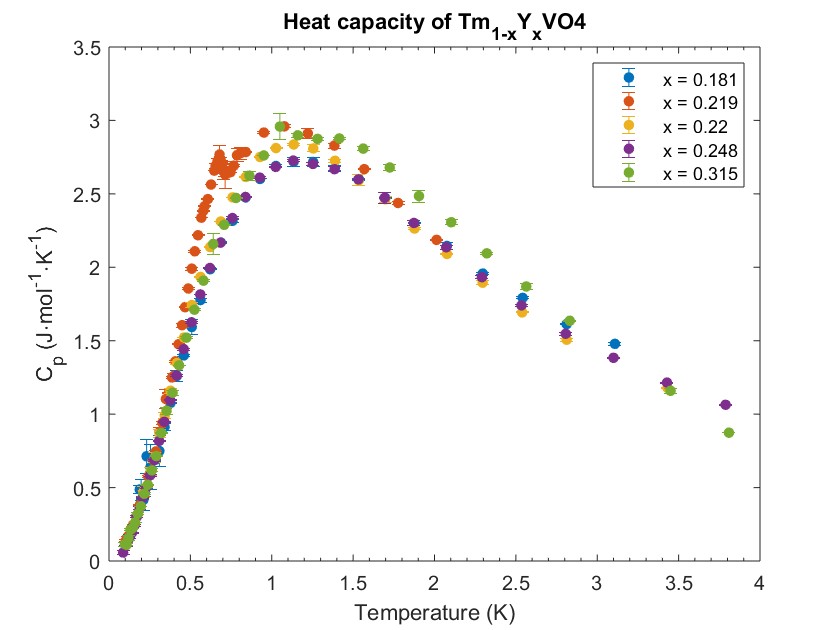

plotAvgCp(avgData,dpg,Lord-1,L)
title(ttlCpY)

## Plot averaged Cp/T data for x>xc

% plotAvgCpoverT(avgData,dpg,Lord-1,L)
% title(ttlCpY)

# Fit data at x=0

## Fit parameters

Tmfmax = [2.1,1.4,0.9,0.2,0.68];% Maximum temperature of mean-field jump for x=0 to x=0.219
% This is a visual estimate of the temperature below which Cp shows a mean-field jump. It only applies for x<xc.
Tc = [2.2,1.57,1.11,0.24,0.69];% Transition temperature
Tschmin = [2.3,1.7,1.2,0.25,0.7];% temperature above which the data are essentially Schottky-like
x0 = [1e-7 0.5];% range of the pseudospin

## Prepare data and fit function

only include temperatures below the transition temperature

for ii=1:5
    avgData(ii).Tord = avgData(ii).T(avgData(ii).T<Tmfmax(ii));
    avgData(ii).Tsch = avgData(ii).T(avgData(ii).T>Tschmin(ii));
    avgData(ii).gamma = 0.2*ones(1,length(avgData(ii).Tord));% initialize pseudospin array
    avgData(ii).g = @(t) fzero(@(x) Tc(ii)*2*x./atanh(2*x)-t,x0);
% g is the total pseudospin as a function of measured temperature t (see below)
    avgData(ii).Cpord = avgData(ii).Cp(avgData(ii).T<Tmfmax(ii));
    avgData(ii).Cpsch = avgData(ii).Cp(avgData(ii).T>Tschmin(ii));
end

The expression of the anonymous function inside fzero is that of a reduced temperature defined as T_caluclated - T_measured, such that it takes the value zero when T_calculated = T_measured. This expression results from inverting the self-consistent equation 2*gamma = th(beta*gamma/2), where gamma is the total pseudospin and beta is the inverse temperature beta = 1/(k_B*T). Therefore, when the function takes the value zero, the correponding abscissa is the value of the total pseudospin at the measured temperature.

Note: the equation 2*gamma = th(beta*gamma/2) is for a reduced beta = beta/beta_c such that k_B*T_c/J_0 = 1/4. In order to get the actual value of the critical temperature, one needs to multiply k_B*T by 4*T_c. The factor 2 in the numerator of the function results from the multiplication by 4 and the factor Tc is the actual value of the transition temperature (estimated visually).

## Determine the total pseudospin gamma for the averaged data

for ii=1:5
    for jj=1:length(avgData(ii).gamma)
        avgData(ii).gamma(jj) = avgData(ii).g(avgData(ii).Tord(jj));
    end
end

## Plot gamma  for the averaged data

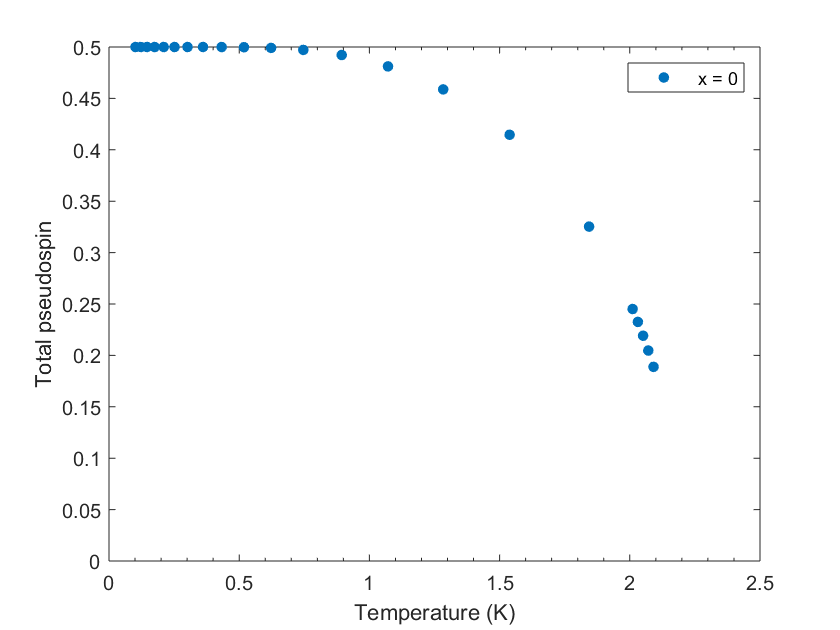

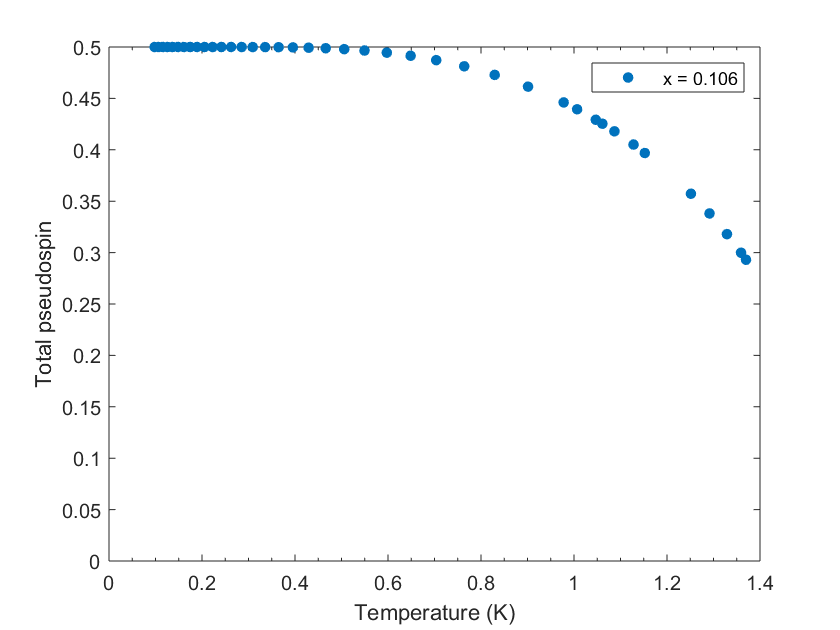

for ii=1:2
    figure 
    plot(avgData(ii).Tord,avgData(ii).gamma,'.','DisplayName',['x = ',num2str(dpg(ii))])
    xlabel('Temperature (K)')
    ylabel('Total pseudospin')
    legend('show')
    ylim([0 0.5])
end

## Fit the data at x=0

See function fitCpvsPseudospin.m

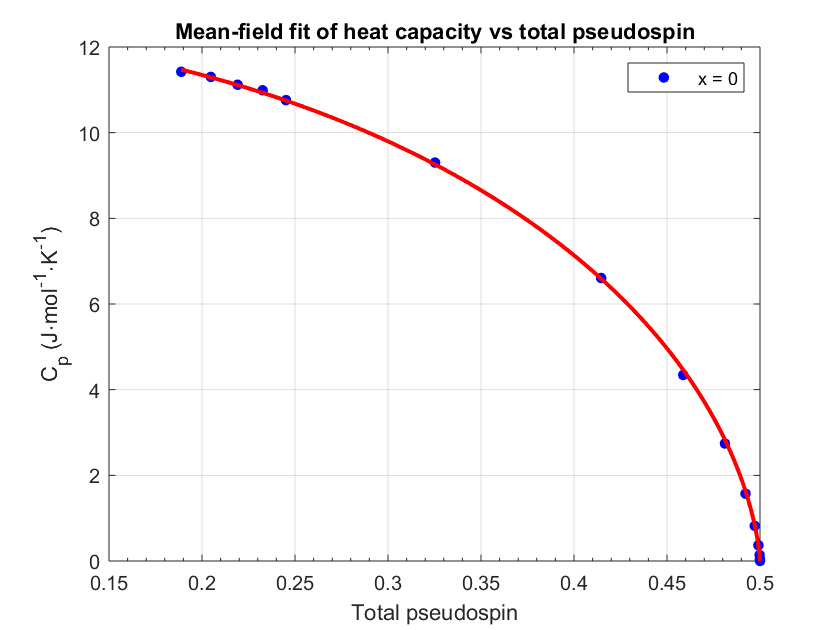

    'Coeffs for x='    [0]    'A'



    8.3047



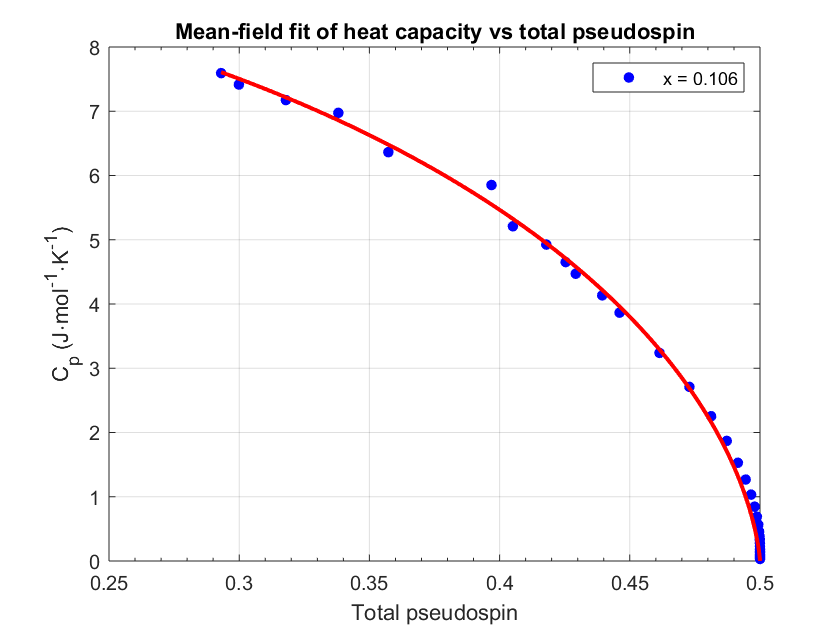

    'Coeffs for x='    [0.1060]    'A'



    6.3606



for ii=1:2
    [avgData(ii).fitCp, avgData(ii).gof] = fitCpvsPseudospin(avgData(ii).gamma,avgData(ii).Cpord,'C_p (J\cdotmol^{-1}\cdotK^{-1})');
% The third argument of the fitting function is an optional argument
% that defines the label of the y axis of the plot
    legend(['x = ',num2str(dpg(ii))])
    disp(['Coeffs for x=',dpg(ii),coeffnames(avgData(ii).fitCp)'])
    disp(coeffvalues(avgData(ii).fitCp))
end

## Fitting function for Cp vs pseudospin

f = @(x) (atanh(2.*x)).^2.*(1-4.*x.^2)./(1-(1-4.*x.^2).*atanh(2.*x)./(2.*x));
% fplot(f,x0);% plot the function on its full interval

% G = [logspace(-7,-2,10),0.02:0.01:0.48,0.5-logspace(-2,-7,10)];% range of pseudospin
G = [0.01:0.01:0.48,0.5-logspace(-2,-15,50)];% range of pseudospin
Tfit = ones(length(Tc),length(G));
for ii=1:2
    Tfit(ii,:) = Tc(ii)*2*G./atanh(2*G);% temperature interval corresponding to the full pseudospin interval
%     figure
%     for each doping level
%     plot(Tfit(ii,:),f(G))% plot Cp fit function on the temperature interval for each doping
end

## Plot data and fit as a function of temperature

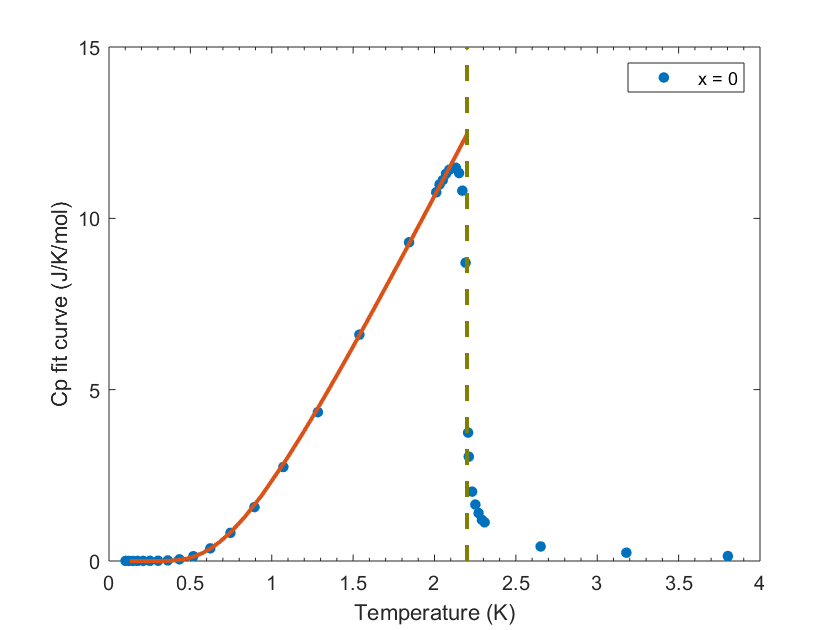

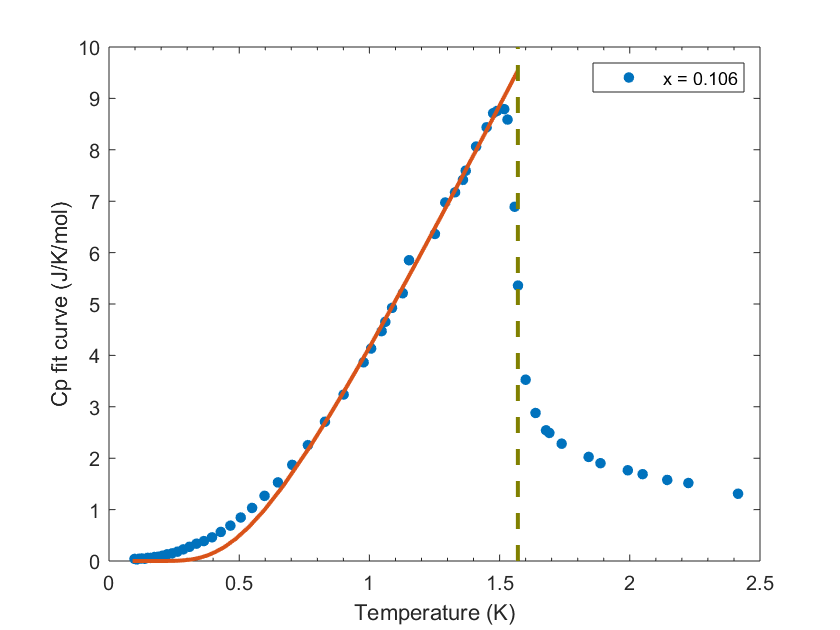

for ii=1:2
    figure 
    plot(avgData(ii).T,avgData(ii).Cp,'.')
    hold on
    plot(Tfit(ii,:),avgData(ii).fitCp.A*f(G));%,'DisplayName',['x = ',num2str(dpg(ii))])
    line([Tc(ii),Tc(ii)],ylim,'Color',[0.5 0.5 0],'LineStyle','--')
    xlabel('Temperature (K)')
    ylabel('Cp fit curve (J/K/mol)')
    legend(['x = ',num2str(dpg(ii))])
%     ylim([0 0.5])

hold off
end

# Fit data for x>0 as sum of mean-field jump + Schottky anomaly

This is the initial step where only the data below T_Q was fitted. Since the newest version includes both below and above T_Q and is more accurate, this should be deleted.

## Mean-field Cp + Normal distribution of Schottky anomalies

% Set up normal distribution of Schottky fittype and options.
% ftnorm = fittype(@(An,mu,sgm,x) fnorm(An,mu,sgm,Ttrans,x),...
% ftmfnorm = fittype(@(Amf,An,mu,sgm,x) fmf(x,Amf)+integral(@(D)(fschott(x,Ttrans,An,D,mu,sgm)),0,inf,'ArrayValued',true),...
ftmfnorm = fittype(@(Amf,An,mu,sgm,x) fmf(x,Amf)+fnrmps(An,mu,sgm,Tc(2),x),...
'independent', 'x', 'dependent', 'y' );

opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
% opts.StartPoint = [1 1 1];% An,mu,sgm in this order
% opts.Lower = [1 2 0];
opts.StartPoint = [1 1 1 1];% Amf,An,mu,sgm in this order
opts.Lower = [1 1 2 0];
% opts.Upper = [7 Inf 4 Inf];

% Fit normal distribution of Schottky model to data below Tmfmin
disp(['Coeffsnorm names',coeffnames(ftmfnorm)'])

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    1.0000   36.5899    7.1467    2.8301



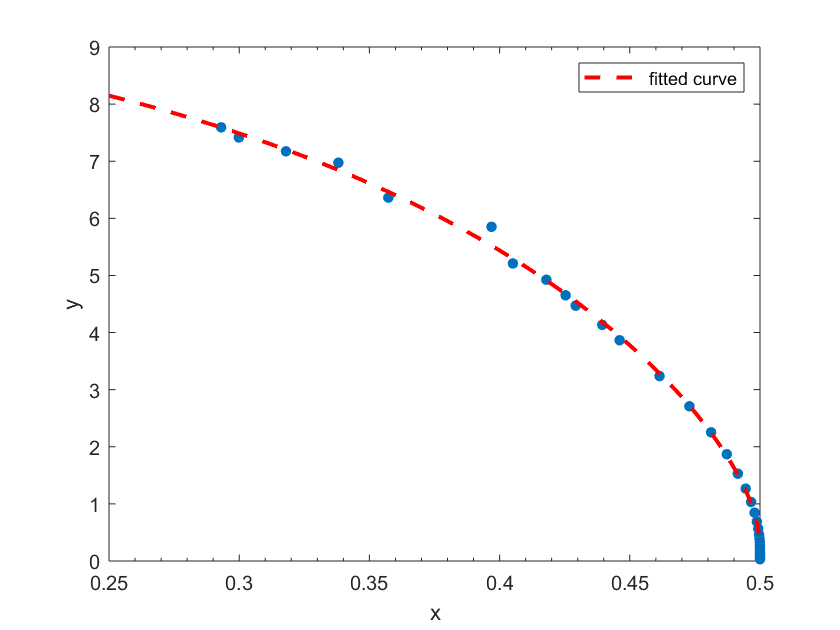

for i=2
    [avgData(i).fitresnorm, avgData(i).gof] = fit(avgData(i).gamma', avgData(i).Cpord', ftmfnorm, opts );
    avgData(i).Coeffsnorm = coeffvalues(avgData(i).fitresnorm);
    disp(avgData(i).Coeffsnorm)
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).gamma', avgData(i).Cpord','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitresnorm,'--r');%,'DisplayName','Normal');
end

## Plot fit for x>0 as a function of temperature

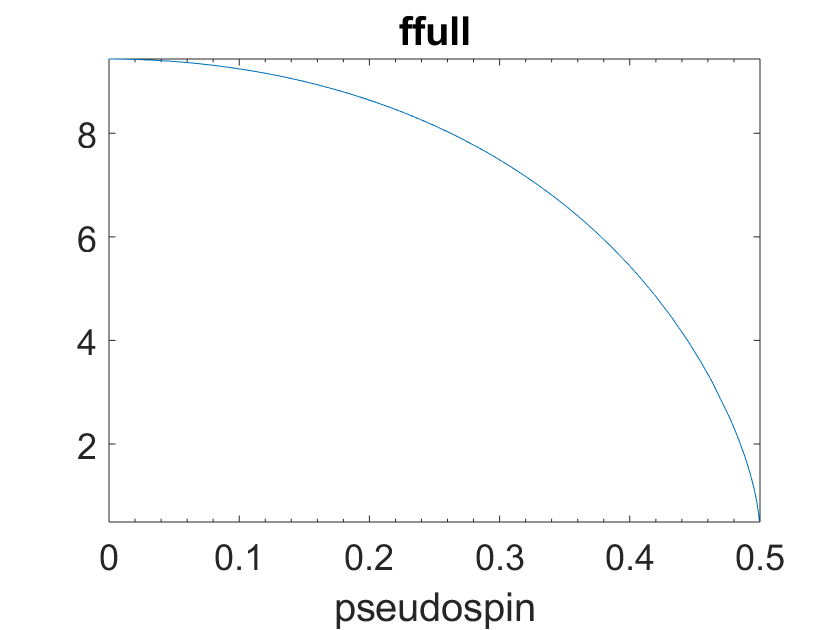

Amf = ones(1,length(avgData(ii)));
An = ones(1,length(avgData(ii)));
mu = ones(1,length(avgData(ii)));
sgm = ones(1,length(avgData(ii)));
for ii=2
    Amf(ii) = avgData(ii).fitresnorm.Amf;
    An(ii) = avgData(ii).fitresnorm.An;
    mu(ii) = avgData(ii).fitresnorm.mu;
    sgm(ii) = avgData(ii).fitresnorm.sgm;
%     fnormps = @(x) integral(@(D)(fschott(x,An(ii),D,mu(ii),sgm(ii))),0,inf,'ArrayValued',true);
%     figure
%     fplot(@(x)fnorm(An(ii),mu(ii),sgm(ii),Tc(ii),x),x0);% plot the function on its full interval
%     xlabel('pseudospin')
%     title('fnorm')
    figure
    ffull = @(x) fmf(x,Amf(ii))+fnrmps(An(ii),mu(ii),sgm(ii),Tc(ii),x);
    fplot(ffull,x0);% plot the function on its full interval
    xlabel('pseudospin')
    title('ffull')
end

## Plot normal distribution of Schottky as a function of temperature

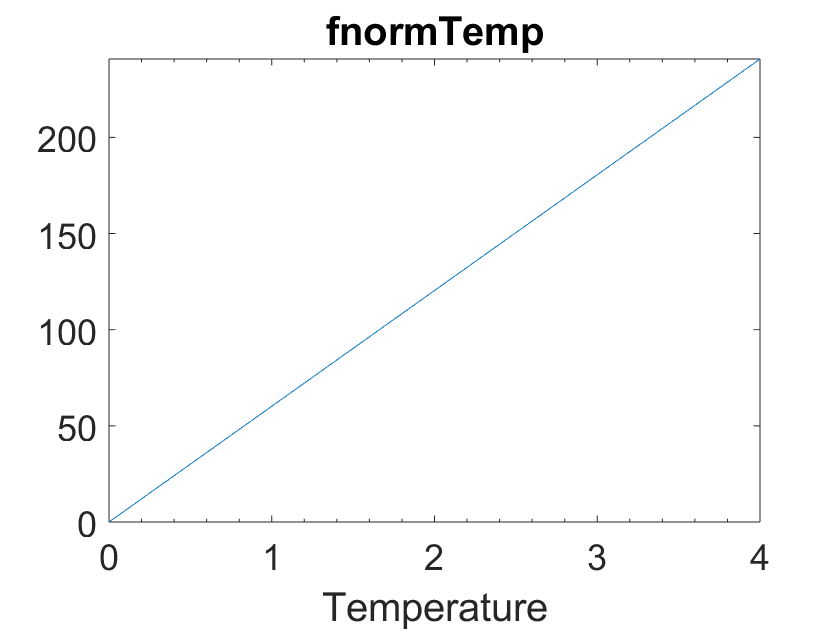

for ii=2;
    fnormTemp = @(x) integral(@(D)(fSchTemp(x,An(ii),D)),0,inf,'ArrayValued',true);
% same as fnormps but as a function of temperature
    figure
    fplot(fnormTemp,[0 4]);% plot the function on its full interval
    xlabel('Temperature')
    title('fnormTemp')
end

## Plot data and full fit as a function of temperature

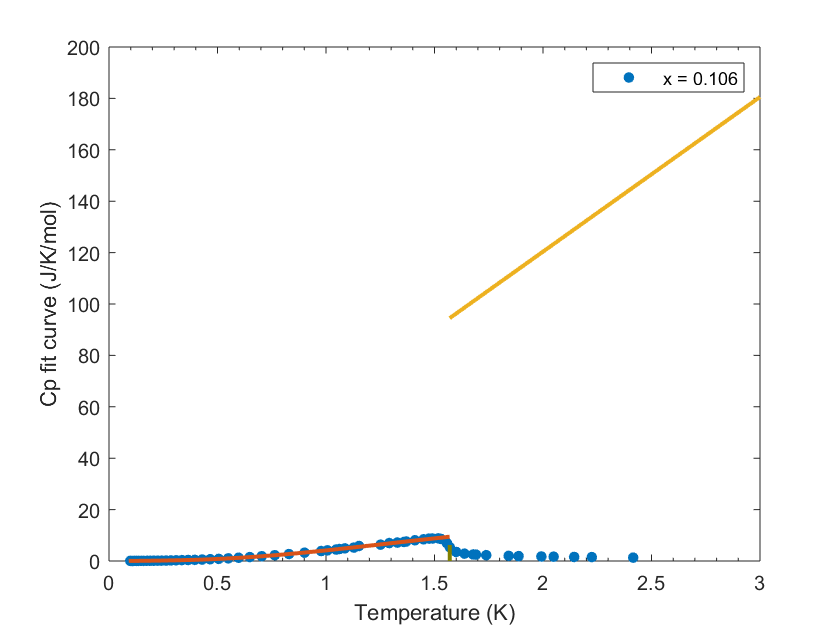

for ii=2
    ht = linspace(Tc(ii),3,20);% range of temperatures above Tc
    figure 
    plot(avgData(ii).T,avgData(ii).Cp,'.')
    hold on
    plot(Tfit(ii,:),ffull(G));%,'DisplayName',['x = ',num2str(dpg(ii))])
    line([Tc(ii),Tc(ii)],ylim,'Color',[0.5 0.5 0],'LineStyle','--')
    plot(ht,fnormTemp(ht));
    xlabel('Temperature (K)')
    ylabel('Cp fit curve (J/K/mol)')
    legend(['x = ',num2str(dpg(ii))])
%     ylim([0 0.5])
    hold off
end

Change fit parameters in order to better fit data above Tc

Perhaps make it a broken segment fit (see Matlab online help for fittype) to include both? Or at least try and fit the data above Tc separately and iterate with the values of the fit parameters below Tc

## Fit normal distribution of Schottky model to data above Tschmin

% ftnorm = fittype(@(An,mu,sgm,T) integral(@(D)fSchTemp(T,An,D,mu,sgm),0,inf,'ArrayValued',true),...
ftnorm = fittype(@(An,mu,sgm,T) fnrmtemp(An,mu,sgm,T),...
    'independent', 'T', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 1];% An,mu,sgm in this order
opts.Lower = [1 0 0];
opts.Upper = [10 4 Inf];

disp(['Coeffsnorm names',coeffnames(ftnorm)'])

    'Coeffsnorm names'    'An'    'mu'    'sgm'



    9.9028    1.8887    0.0030



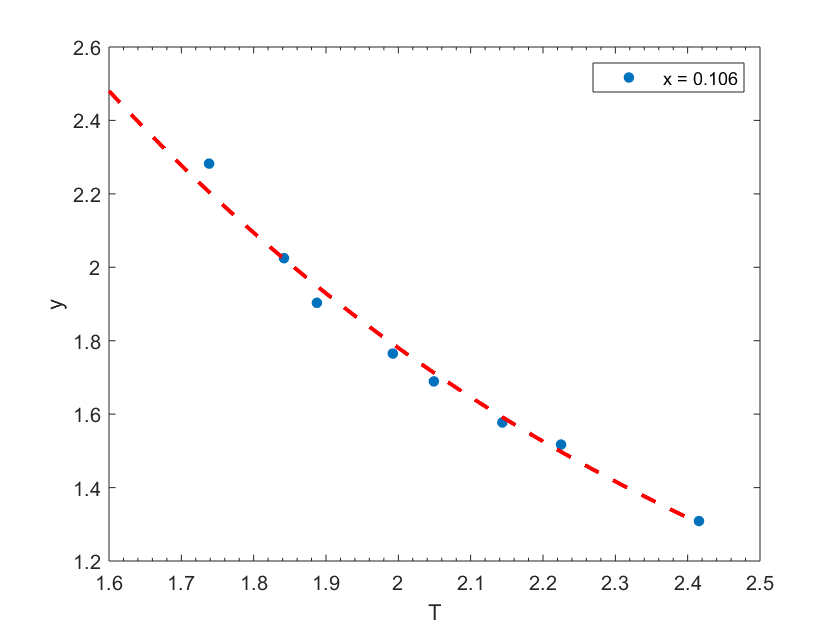

for i=2
    [avgData(i).fitSchNorm, avgData(i).SNgof] = fit(avgData(i).Tsch', avgData(i).Cpsch', ftnorm, opts );
    disp(coeffvalues(avgData(i).fitSchNorm))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).Tsch', avgData(i).Cpsch','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitSchNorm,'--r');%,'DisplayName','Normal');
end

## Fit full curve piecewise with *normal* Schottky PDF

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    4.9012    5.2241    4.4751    2.1411



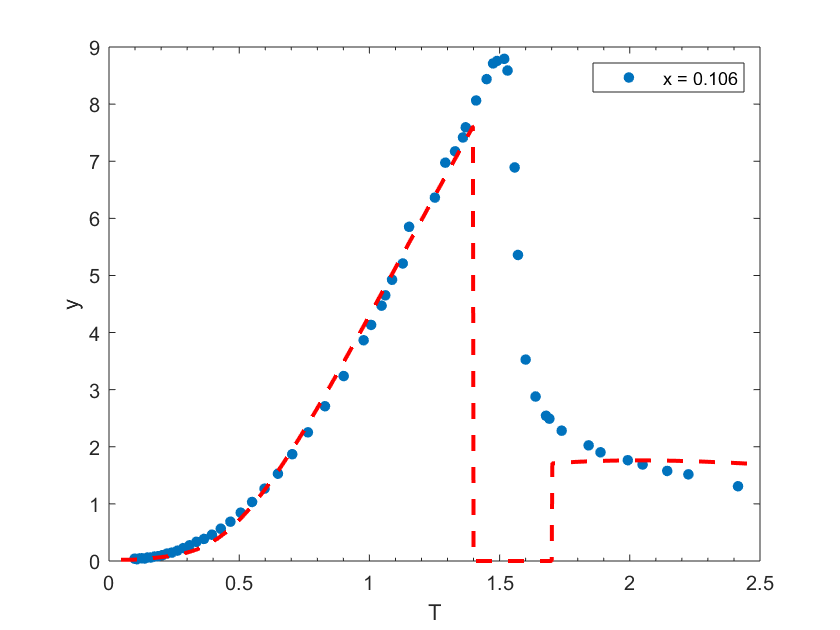

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    1.2050    7.6543    2.7464    0.8957



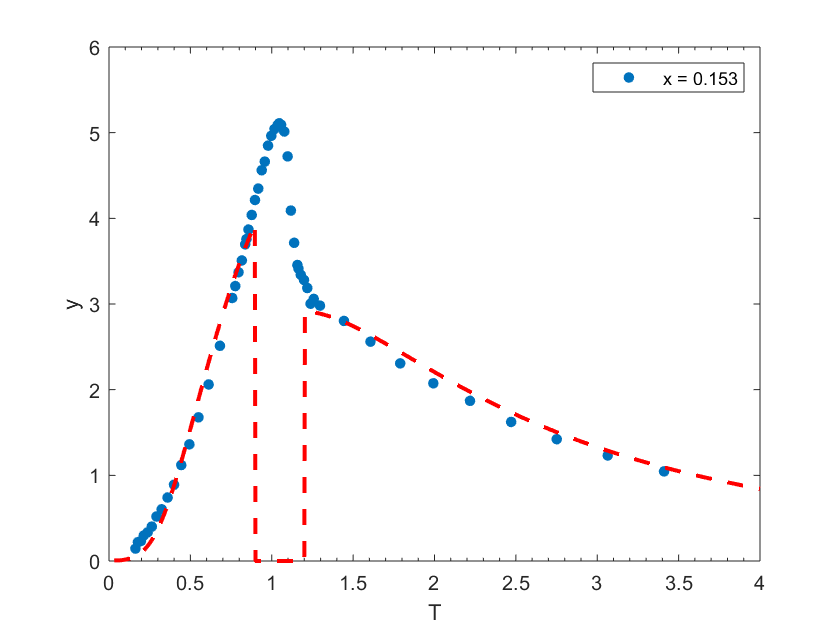

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    0.0577    9.5597    2.3567    1.6505



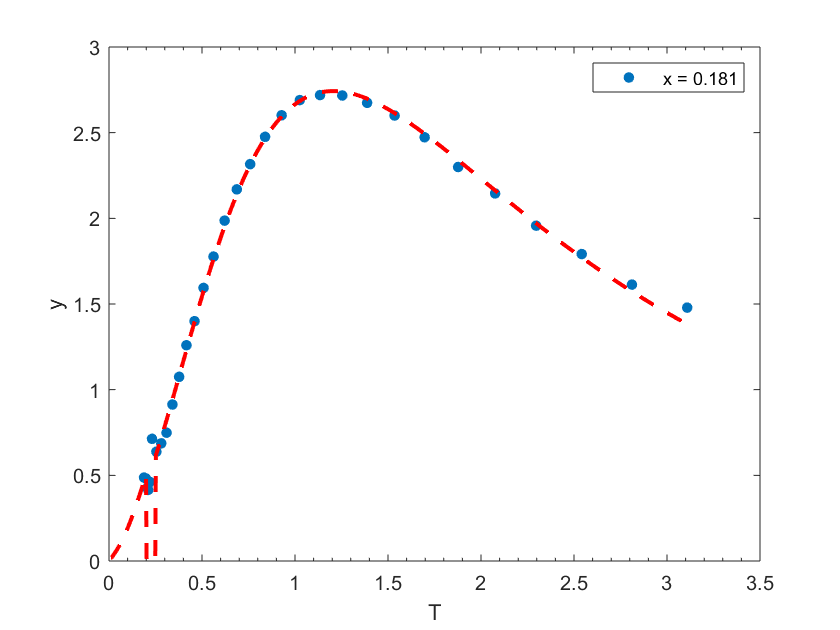

    'Coeffsnorm names'    'Amf'    'An'    'mu'    'sgm'



    0.2041    9.0494    2.3455    1.1537



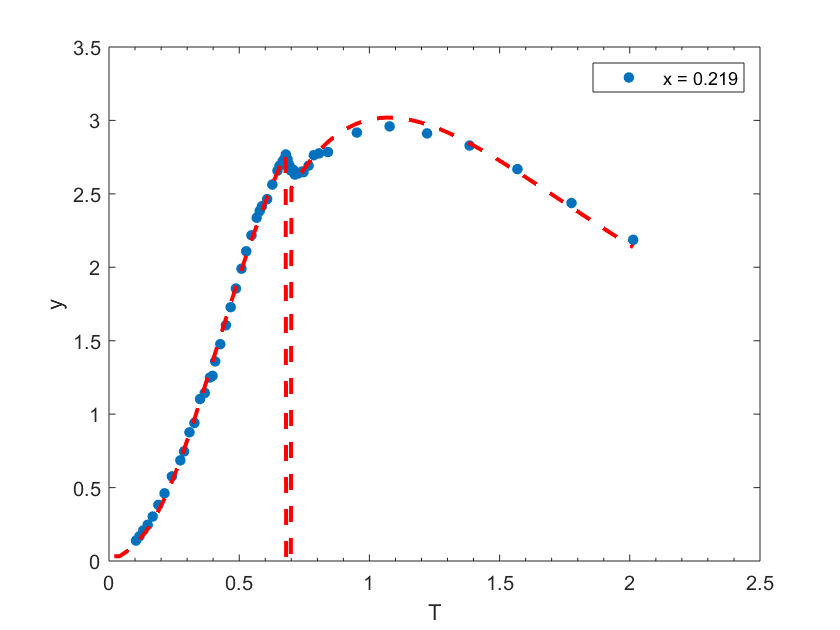

for i=2:5
%     ftfull = fittype(@(An,mu,sgm,T) fitCpdop(T,Tschmin(i),An,mu,sgm),...
%     ftfull = fittype(@(Amf,An,mu,sgm,T) fitCpdop(T,avgData(i).gamma,Tmfmax(i),Tschmin(i),Amf,An,mu,sgm),...
    ftfull = fittype(@(Amf,An,mu,sgm,T) fitCpnrm(T,Tc(i),Tmfmax(i),Tschmin(i),Amf,An,mu,sgm),...
    'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
%     opts.StartPoint = [1 1 1];% Amf,An,mu,sgm in this order
%     opts.Lower = [0 0 0];
    opts.StartPoint = [1 1 1 1];% Amf,An,mu,sgm in this order
    opts.Lower = [0 0 0 0];
%     opts.Upper = [Inf Inf 5 5 ];

% Fit normal distribution of Schottky model to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftfull)'])
    [avgData(i).fitfull, avgData(i).ffgof] = fit(avgData(i).T', avgData(i).Cp', ftfull, opts );
    disp(coeffvalues(avgData(i).fitfull))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitfull,'--r');%,'DisplayName','Normal');
    legend(['x = ',num2str(dpg(i))])
end

## Fit full curve piecewise with *uniform* Schottky PDF

    'Coeffsnorm names'    'Amf'    'Au'    'di'    'df'



    1.1616    2.7702    1.3939    4.1094



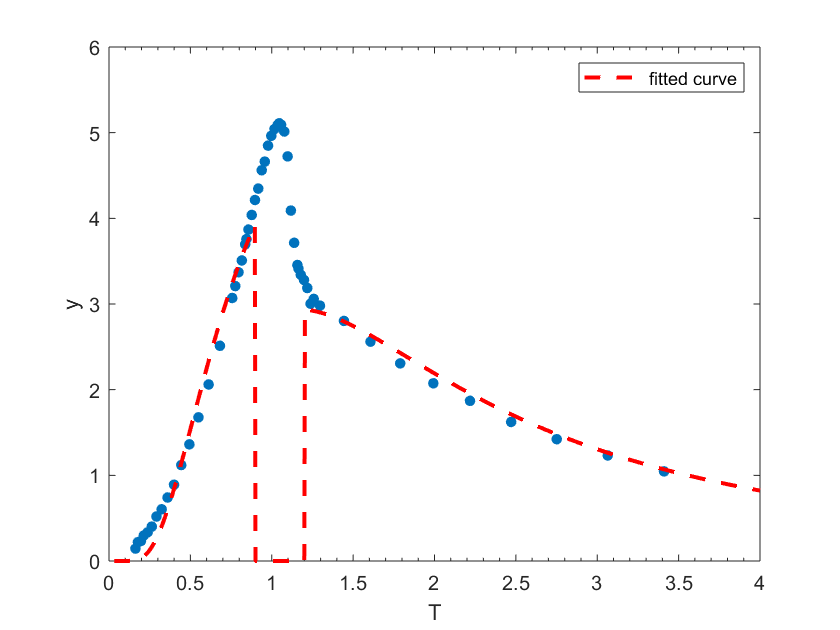

for i=3
    ftfull = fittype(@(Amf,Au,di,df,T) fitCpunif(T,Tc(i),Tmfmax(i),Tschmin(i),Amf,Au,di,df),...
    'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [1 1 1 1];% Amf,An,mu,sgm in this order
    opts.Lower = [0 0 0 0];
%     opts.Upper = [Inf Inf 5 5];

% Fit normal distribution of Schottky model to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftfull)'])
    [avgData(i).fitfull, avgData(i).ffgof] = fit(avgData(i).T', avgData(i).Cp', ftfull, opts );
    disp(coeffvalues(avgData(i).fitfull))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitfull,'--r');%,'DisplayName','Normal');
end

function y = fmf(x,Amf)% Mean-field expression of heat capacity as a function of pseudospin x
    y = Amf*(atanh(2*x)).^2.*(1-4*x.^2)./(1-(1-4*x.^2).*atanh(2*x)./(2*x));
end

function y = fschps(x,Ttrans,A,D)% Schottky anomaly as a function of pseudospin x
    y = A*(D./(2*Ttrans*2*x./atanh(2*x))).^2.*sech(D./(2*Ttrans*2*x./atanh(2*x))).^2 ;
end

function y = fnrmps(An,mu,sgm,Ttrans,x)% Normal PDF of Schottky anomaly as a function of pseudospin x
    y = integral(@(D)(fschps(x,Ttrans,An,D).*normpdf(D,mu,sgm)),0,inf,'ArrayValued',true);
end

function y = funifps(Au,di,df,Ttrans,x)% Uniform PDF of Schottky anomaly as a function of temperature T
    y = integral(@(D) fschps(x,Ttrans,Au,D),di,df,'ArrayValued',true);
end

function y = fSchTemp(T,A,D)% Schottky anomaly as a function of temperature T
    y = A*(D./(2*T)).^2.*sech(D./(2*T)).^2;
end

function y = fnrmtemp(An,mu,sgm,T)% Normal PDF of Schottky anomaly as a function of temperature T
    y = integral(@(D)fSchTemp(T,An,D).*normpdf(D,mu,sgm),0,inf,'ArrayValued',true);
end

function y = funiftemp(Au,di,df,T)% Uniform PDF of Schottky anomaly as a function of temperature T
    y = integral(@(D) fSchTemp(T,Au,D),di,df,'ArrayValued',true);
end

function y = pseudospin(T,Ttrans,Tmf)
%%% calculate pseudospin as a function of temperature T from T=0 to T=Tmf
%%% for a given transition temperature Ttrans
    Tord = T(T<Tmf);
    y = 0.2*ones(1,length(Tord));% initialize pseudospin array
    g = @(t) fzero(@(x) Ttrans*2*x./atanh(2*x)-t,[1e-7 0.5]);
    for jj=1:length(y)
        y(jj) = g(Tord(jj));
    end
end

function y = fitCpnrm(T,Ttrans,Tmf,Tsch,Amf,An,mu,sgm)
%%% Fitting function for heat capacity as a combination of : 
%%% a mean-field jump and *normal* Schottky distribution below Tmf 
%%% a *normal* Schottky distribution above Tsch
    y = zeros(size(T));
    gamma = pseudospin(T,Ttrans,Tmf);
    y(T<Tmf) = fmf(gamma,Amf) + fnrmps(An,mu,sgm,Ttrans,gamma);%
    y(T>Tsch) = fnrmtemp(An,mu,sgm,T(T>Tsch));
end

function y = fitCpunif(T,Ttrans,Tmf,Tsch,Amf,Au,di,df)
%%% Fitting function for heat capacity as a combination of: 
%%% a mean-field jump and *uniform* Schottky distribution below Tmf 
%%% a *uniform* Schottky distribution above Tsch
    y = zeros(size(T));
    gamma = pseudospin(T,Ttrans,Tmf);
    y(T<Tmf) = fmf(gamma,Amf) + funifps(Au,di,df,Ttrans,gamma);%
    y(T>Tsch) = funiftemp(Au,di,df,T(T>Tsch));
end

Note: all these functions need to be defined **before** the function is called for fitting